# Channel Matched Filter Equalizer

% 1D Antenna Formation
% Uplink with IF = 0
% Different AOA for Users

## Global Parameter

clc;
clearvars;

% Number of Antennas and Users
M1 = 8;
M2 = 8;

M2 = 8

M = M1 * M2;
K = 19;

% Channel Length
L = 4;

% Block Length
T = 100;

% Cyclic Prefix Length
Tc = 20;

% Monte-Carlo Parameter
Ni = 50;

% Plot Points
Pi = 500;

% Normalized Distance
dn = 1;

% Range of Power
r = linspace(0.01,10,Pi);
e = mag2db(r) / 2;

## Distance Matrix

% Linear
for i = 1 : M
    for j = 1 : M
        dist(i, j) = abs(i - j) * dn;
    end
end

% Rectangular
%i = 1;
%for c1 = 1 : M1
%    for r1 = 1 : M2
%        j = 1;
%        for c2 = 1 : M1
%            for r2 = 1 : M2
%                dist(i, j) = (c2 - c1) ^ 2 + (r1 - r2) ^ 2;
%                j = j + 1;
%            end
%        end
%        i = i + 1;
%    end
%end
%dist = sqrt(dist .* dn);

## Bessel Correlation Pattern

eta = 10; % Width of the AOA
mu = linspace(-pi / 2, pi / 2, K); % Mean Direction of the AOA
for k = 1 : K
    arg = eta ^ 2 - 4 * (pi ^ 2) .* dist .^ 2 + 4i * pi * eta * sin(mu(k)) .* dist;
    arg = sqrt(arg);
    A(:, :, k) = besseli(0, arg) ./ besseli(0, eta);
end

## Channel Power Delay Profile

u = (0 : K - 1) / 5; % Phase
for l = 1 : L
    for k = 1 : K
        d1 = exp(-1 * u(k) * (0 : L - 1));
        d(l, k) = exp(-1 * u(k) * (l - 1)) / (sum(d1));
    end
    D1 = diag(d(l, :));
    D(:, :, l) = D1;
end

## Channel Uses

for n = 1 : Ni
    si(:, :, n) = (sqrt(0.5)) * (randn(K, T) + 1i * randn(K, T));
    zi(:, :, n) = (sqrt(0.5)) * (randn(M, T + Tc) + 1i * randn(M, T + Tc));
    
    % Channel State Information
    for l = 1 : L
        for k= 1 : K
            H1 = ((A(:, :, k)) ^ (0.5)) * (sqrt(0.5)) * (randn(M, K) + 1i * randn(M, K));
            D1 = D(:, :, l) .^ (0.5);
            Hl(:, :, k, l, n) = H1 * D1;
            Ql(:, :, k, l, n) = Hl(:, :, k, l, n)'; % Channel Matched Filter Equalizer
        end
    end
    for k = 1 : K
        [AQ(k, n)] = Signal_Power(L, Ql(:, :, k, :, n));
    end
    
    % Composite Effect Matrix
    for l = 1 : L
        for k = 1 : K
            Fl(:, :, k, l, n) = (Ql(:, :, k, l, n)) * (Hl(:, :, k, l, n));
        end
    end
end

% Normalization Factors
A_Q = 1 ./ mean(AQ, 2);

% Desired Signal
for n = 1 : Ni
    for k = 1 : K
        for l = 1 : L
            gk(k, :, n, l) = Fl(k, k, k, l, n) * si(k, :, n);
        end
    end
end
gi = sum(gk, 4);

% Transmitt Signal
xi = si;
for j = 1 : Tc
    xi(:, T + j, :) = xi(:, j, :); % Cyclic Prefix
end

% Channel Output Signal
for n = 1 : Ni
    for l = 1 : L
        for k = 1 : K
            for j = 0 : T + Tc - 1
                rl(:, k , j + 1, n, l) = (Hl(:, :, k, l, n)) * xi(:, mod(j - l, T) + 1, n);
            end
        end
    end
end
ri = sum(rl, 5);

% Received Signal
for n = 1 : Ni
    for l = 1 : L
        for k = 1 : K
            for j = 0 : T + Tc - 1
                yl(: ,j + 1, n, l) = Ql(:, :, k, l, n) * ri(:, k, mod(j + l, T) + 1, n);
            end
        end
    end
end
yi = sum(yl, 4);

% Effective Noise
ni = yi(:, 1 : T, :) - gi;

for n = 1 : Ni
    for l = 1 : L
        for k = 1 : K
            for j = 0 : T + Tc - 1
                AWGNl(:, n, j + 1, l) = Ql(:, :, k, l, n) * zi(:, mod(j + l, T) + 1, n) ./ sqrt(M * K);
            end
        end
    end
end
AWGNi = sum(AWGNl, 4);
AWGN = mean(var(AWGNi, 0, 3), 2); % for each user

## Results

% Capacity
Fl_sum = sum(mean(Fl, 5), 4);
Nl(1, 1 : Pi) = linspace(1 / K, 1, Pi); % New Noise Level
for n = 1 : Ni
    for k = 1 : K
        Sk(k, :, n) = abs(A_Q(k) * (Fl_sum(k, k, k))) ^ 2 * r(:);
        %Ck(k, :, n) = log2(1+  Sk(k, :, n) ./ AWGN(k)); % Old Upper Bound
        Ck(k, :, n) = log2(1 + Sk(k, :, n) ./ (Nl(1, :))); % New Upper Bound
    end
end
C = mean(sum(Ck, 1), 3);

% Achievable Rate
for n = 1 : Ni
    for k = 1 : K
        Sn(k, :, n) = var(A_Q(k) * ni(k, :, n), 0, 2) * r(:) + AWGN(k);
        SNR(k, :, n) = Sk(k, :, n) ./ Sn(k, :, n);
        Rk(k, :, n) = log2(1 + SNR(k, :, n));
    end
end
R = mean(sum(Rk, 1), 3);

## Theoretical Result

for l = 1 : L
    for k = 1 : K
        Vg_1(l, k) = d(l, k) ^ 2;
        Vg_2(l, k) = d(l, k);
    end
end
Vg_11 = sum(Vg_1, 1);
Vg_22 = sum(Vg_2, 1);
Nl(1 : Pi) = linspace(1 / K, 1, Pi);
for k = 1 : K
    Vg(:, k) = (r(:) ./ (M * K)) * (trace(A(:, :, k) ^ 2) * (Vg_11(k)) + (trace(A(:, :, k)) ^ 2) * (Vg_22(k)) .^ 2);
    Vn(:, k) = r(:) * (trace(A(:, :, k) ^ 2) ./ M) * (1 - Vg_2(k) / K) + 1 / K;
    Cth_h(:, k) = log2(1 + Vg(:, k) ./ Nl(:)); % New Upper Bound
    %Cth_h(:, k) = log2(1 + K * Vg(:, k)); % Old Upper Bound
    Rth_k(:, k) = log2(1 + Vg(:, k) ./ Vn(:, k));
end
Cth = sum(Cth_h, 2);
Rth = sum(Rth_k, 2);

## Plots

% Nader's Figure
figure
plot(e, Rth, 'b', e, R, 'r');

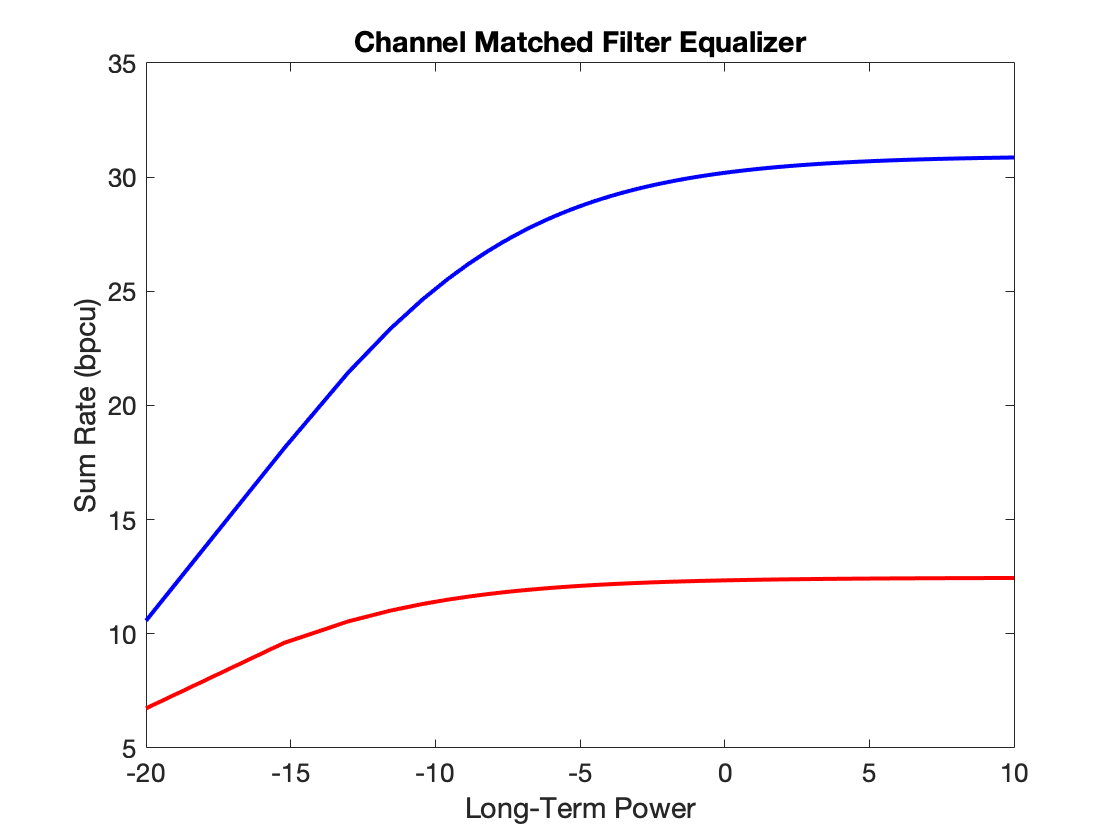

title('Channel Matched Filter Equalizer','fontsize', 15);
xlabel('Long-Term Power', 'fontsize', 15);
ylabel('Sum Rate (bpcu)', 'fontsize', 15);
set(gca, 'fontsize', 13);
set(findall(gca, 'Type', 'Line'), 'LineWidth', 2);


% Gokhan Figures
%figure
%plot(e,Cth,'b',e,Rth,'r');
%title('Channel Matched Filter Equalizer','fontsize',15);
%xlabel('Long-Term Power','fontsize',15);
%ylabel('Sum Rate (bpcu)','fontsize',15);
%set(gca,'fontsize',13);
%set(findall(gca, 'Type', 'Line'),'LineWidth',2);
